# Test CNN.m

## Parameters

folder_ptah                            = './data/tiny-insect-flight';
filename_extension                     = 'jpg';

x                                      = [];
y                                      = [];
divide_param.train_ratio               = 70/100;
divide_param.validation_ratio          = 15/100;
divide_param.test_ratio                = 15/100;

kernel_sizes                           = [20, 20, 10; 10, 10, 5];
kernel_paths                          = {'bipolar', 'ganglion'};
space_value_limits                     = [-1, 1; -1, 1];
time_value_limits                      = [-1, 1; -1, 1];
output_size                            = [20, 20, 20];
resize_method                          = 'crop';

number_of_epochs                       = 100;
learning_rate                          = 0.001;
number_of_validations_faild            = 20;

cost_function                          = @CNN.quadratic_cost_function;
diff_cost_function                     = @CNN.diff_quadratic_cost_function;
activation_function                    = @CNN.rectifier_activation_function;
diff_activation_function               = @CNN.diff_rectifier_activation_function;

delay                                  = 0.1;
number_of_slices                       = 5;

## Neural Network

cnn = CNN();

input = {CNN.make_input(folder_ptah, filename_extension)};

Index exceeds matrix dimensions.

Error in CNN.make_input (line 723)
            I = imread(fullfile(folder_path, files(1).name));

CNN.plot_slice_3darray(input{1}, number_of_slices);

cnn.x = x;
cnn.y = y;
cnn.divide_param = divide_param;

cnn.kernel_sizes = kernel_sizes;
cnn.kernel_paths = kernel_paths;
cnn.space_value_limits = space_value_limits;
cnn.time_value_limits = time_value_limits;
cnn.output_size = output_size;
cnn.resize_method = resize_method;

cnn.number_of_epochs = number_of_epochs;
cnn.learning_rate = learning_rate;
cnn.number_of_validations_faild = number_of_validations_faild;

cnn.C = cost_function;
cnn.C_ = diff_cost_function;
cnn.s = activation_function;
cnn.s_ = diff_activation_function;

cnn.init();

input = cnn.resize_input(input);
output = cnn.out(input);

## Show Results

% cnn.draw_net();
CNN.plot_slice_3darray(input{1}, number_of_slices, true);

Undefined variable "input" or class "input".

CNN.plot_slice_3darray(output{1}, number_of_slices, true);

CNN.plot_slice_3darray(cnn.w{1}, number_of_slices, true);
CNN.plot_slice_3darray(cnn.w{2}, number_of_slices, true);

cnn.plot_kernel(2);

% CNN.movie_slice_3darray(input{1}, delay, true);
% CNN.movie_3darray(input{1}, delay);

% cnn.plot_fit();
% cnn.plot_all_regressions();
% cnn.plot_error_histogram();
% cnn.plot_total_cost_history();
% cnn.animate_fit_history(delay)

## Make Data

N                                     = 100;   % number of data
cnn.make_data(N);
cnn.save('cnn');

## Learning

clear();

sigma                                 = 0.01; % gaussian noise to kernels
cnn = CNN.load('cnn');
cnn.add_noise_to_w(sigma);
tic();
cnn.run();
toc();

Elapsed time is 105.565531 seconds.


## Show Results

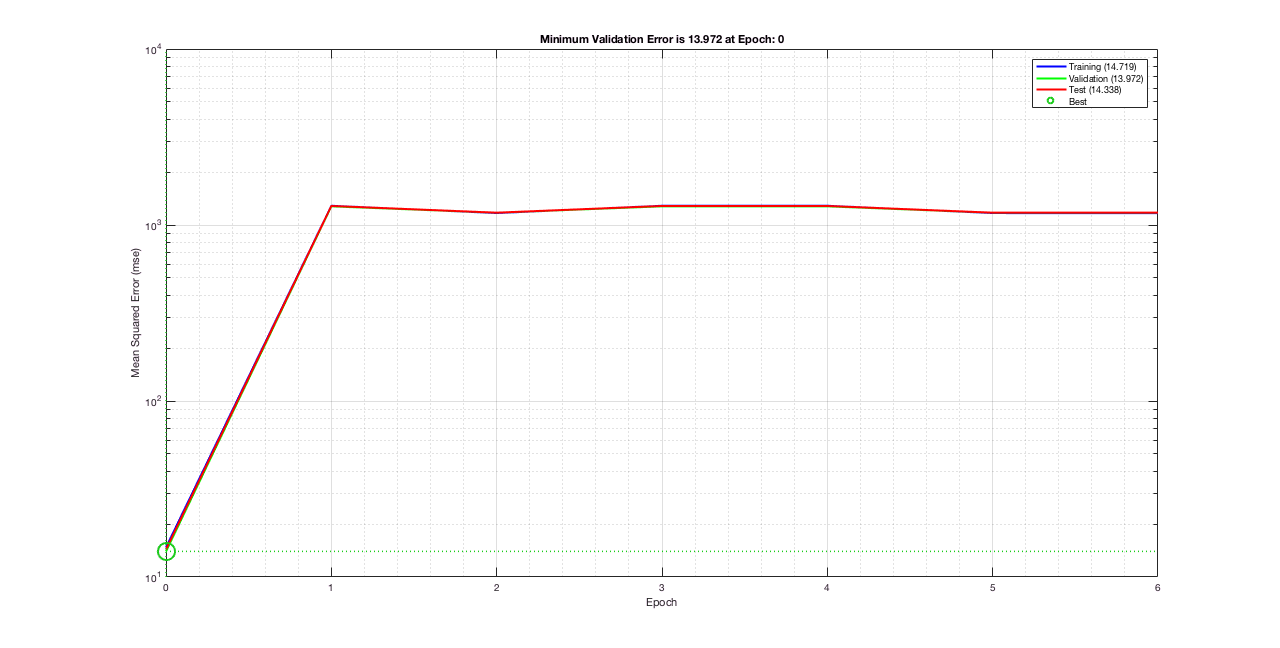

cnn.plot_total_cost_history();